**Skills 10: Photosynthesis and Group Dynamics**

**23.)**

**Given**

Delaware River depth and light intensity data:

ddel = [0, 1, 2, 3, 4, 5, 6, 7]; %depth in ft
Idel = [100, 42, 18.5, 11.5, 5.1, 2.0, 0.73, 0.27]; %Relative light intensity

Lake Tahoe depth and light intensity data:

dtah = [0, 33, 60, 100, 200]; %depth in ft
Itah = [100, 30, 18, 9, 2]; %Relative light intensity

**Required**

- Plot the data as a function of depth

- Estimate the extinction coefficients, $K_e$ (to base e) in 1/ft for both sets of data. Also estimate the depth at which 1% of the surface light still exists.

**Sketch**

**Theory**

- I will plot the light intensity data as a function of depth using a simple line graph. I will then estimate $K_e$ using Beer's Law.

Beer's Law: $\ln E_Z =\ln E_0 -K_e Z\longrightarrow K_e =\frac{\ln E_Z -\ln E_0 }{-Z}$

- I will estimate the depth at which 1% of the surface light still exists through linear regression of the line of lnE vs depth. 

**Assumptions**

- I assume that light intensity will eventually equal zero at some point.

- I assume that the E variable in Beer's law = light intensity.

**Solution**

- First, I plotted light intensity vs depth:

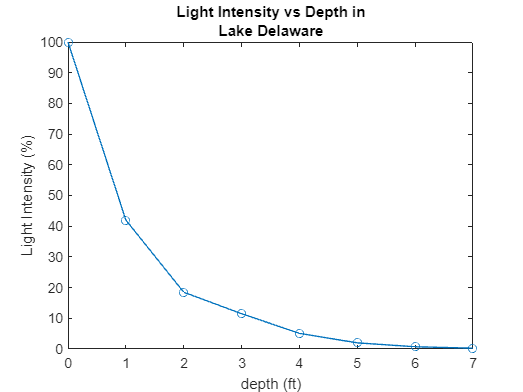

figure
plot(ddel,Idel,'o-')

title(["Light Intensity vs Depth in", "Lake Delaware"])
ylabel("Light Intensity (%)")
xlabel("depth (ft)")

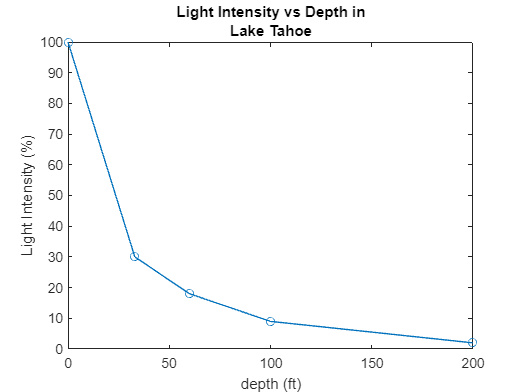

figure
plot(dtah,Itah,'o-')

title(["Light Intensity vs Depth in", "Lake Tahoe"])
ylabel("Light Intensity (%)")
xlabel("depth (ft)")

- I then used Beer's Law to estimate $K_e$ at 4 ft in Lake Delaware and 100 ft in Lake Tahoe:

Lake Delaware: $K_e =\frac{\ln E_Z -\ln E_0 }{-Z}$ = $\frac{\ln 5\ldotp 1-\mathrm{ln100}}{-5\ldotp 1}=0\ldotp 58\;{\mathrm{ft}}^{-1}$

Lake Tahoe: $K_e =\frac{\ln E_Z -\ln E_0 }{-Z}$ = $\frac{\mathrm{ln9}-\mathrm{ln100}}{-100}=0\ldotp 024\;{\mathrm{ft}}^{-1}$

- I then estimated the depth at which 1% of surface light exists in each lake ($E_Z =1%$) using the Beer's Law equation to solve for Z.

Lake Delaware: $Z=\frac{\ln E_Z -\ln E_0 }{-K_e }=\frac{\ln 1-\mathrm{ln100}}{-0\ldotp 58}=7\ldotp 94\;\mathrm{ft}$

Lake Tahoe: $Z=\frac{\ln E_Z -\ln E_0 }{-K_e }=\frac{\ln 1-\mathrm{ln100}}{-0\ldotp 024}=192\ldotp 9\;\mathrm{ft}$

**Discussion**

The calculated values at which 1% of light still exists do not match perfectly with the data, but the relationship is still pretty close. From looking at the data, Lake Tahoe obviously is a much clearer lake with much less turbidity than Lake Delaware and is likely among other factors a reason why Lake Tahoe is a world-renowed vacation destination and Lake Delaware's Wikipedia article is only 1 sentence.

.........................................................................................................................................................................................

**24.)**

**Given**

- 
$$T=10\;C$$


- 
$$f=0\ldotp 6$$


- 
$$I_S =350\;\mathrm{ly}/\mathrm{day}$$


- 
$$K_e =0\ldotp 5/m$$


- 
$$G_{\max } =1\ldotp 8/\mathrm{day}$$


- 
$$I_T =500\;\mathrm{ly}/\mathrm{day}$$


- 
$$K_{\mathrm{mp}} =2\;\mu g\;P/L$$


- 
$$\mu_R =0\ldotp 15/\mathrm{day}$$


- 
$$H=17\;m$$


**Required**

- If nutrients are not limiting, what are the growth, death (no zooplankton), and net growth rates of the phytoplankton assuming no settling? If the initial phytoplankton chlorolphyll at t=0 is $1\ldotp 0\;\mu g/L$, what would the phytoplankton level be if this net growth rate persisted for 30 days?

- Plot the relationship of growth rate vs available P concentration.

- Repeat part 1 if the ambient available P concentration is $2\;\mu g\;P/L$.

**Sketch**

**Theory**

- I will use first-order kinetics to solve part 1 since there are no limiting nutrients.

- I plan to use Michaelis-Menten kinetics to solve this problem using P as the limiting nutrient for part 3.

**Assumptions**

- 
$$G_{\max } =\mu_{\max }$$


- No settling

- Net growth rate = growth rate - death rate

**Solution**

**Discussion**